Brief summary of this function.

time in seconds

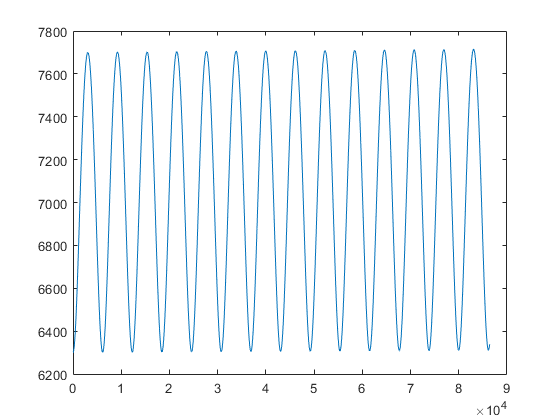

close all; clear; clc;


[R,V,E,tv] = integrate2Body(7000,0.1,1*60*60*24);
figure;
plot(tv,R);

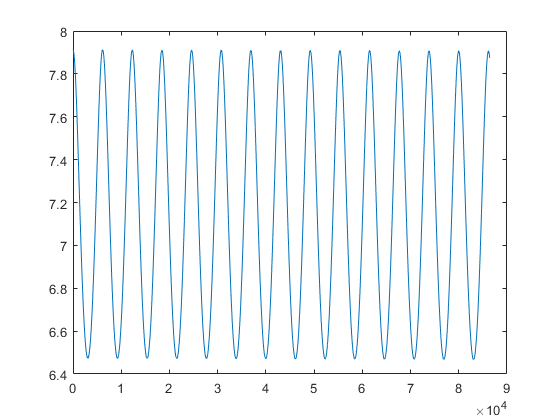

figure;
plot(tv,V);

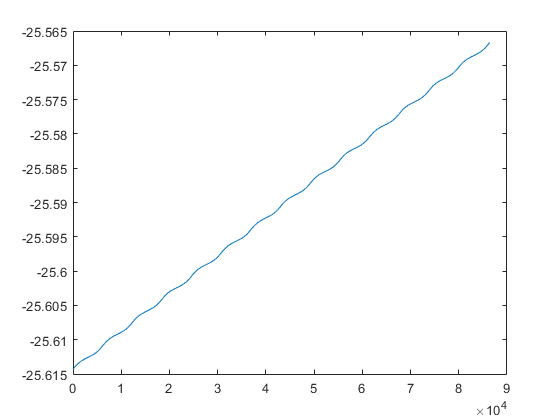

figure;
plot(tv,E);

function [R,V,E,tv] = integrate2Body(a,e,t)
    mu=3.586e5;
    dt = .01;
    tv = 0:dt:t;
    timeSteps = length(tv);
    r0 = a*(1-e);
    v0 = sqrt(mu*((2/r0)-(1/a)));
    E0 = ((v0^2)/2)-(mu/r0);
    
    X0 = [r0;0;0;v0];
    xdd0 = -(mu/r0^3)*X0(1); %x double dot
    ydd0 = -(mu/r0^3)*X0(2);%y double dot
    
    fxt = [0; v0; xdd0; ydd0];
    
    R = zeros(1,timeSteps);
    R(1) = r0;
    V(1) = v0;
    E(1) = E0;
    XV = X0;
    
    
    for i = 2:timeSteps % you can start with t=1 or t=2 and you will get different but correct answers
        XV = XV + fxt*dt;
        V(i) = sqrt((XV(3))^2+(XV(4))^2);
        R(i) = sqrt((XV(1))^2+(XV(2))^2);
        %E(i)= (1/2)*V(2)^2-mu/R(i);
        fxt = [XV(3); XV(4); (-mu/R(i)^3)*XV(1); (-mu/R(i)^3)*XV(2)];
    end
    
    E = (1/2).*V.^2-mu./R;
end